Lab 3

*Problem 1*

In our first example we are looking at the temperature reading  (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look  at the data it is mostly consistent with 12 Kelvin to within the 0.4  degree precision of the thermometry and the thermal control system  (standard deviation). However, there are times when the thermal control  system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously  high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the  thermal control system was not working (and the temperature was truly  off from nominal). While it is possible to have an error in the  thermometry such that the true temperature was fine, and we just had a  wonky reading, in an abundance of caution we want to throw those values  out too.

To make this a bit concrete, we will simulate a little data. Start by  simulating 100k 'good' data points assuming Gaussian fluctations, and  because we are playing god adding the following 'bad' datapoints:  {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7}

- Explore the data with appropriate plots:

We plot the 

clear all; close all; clc;
x = 1:100000;
temp = 0:(25/length(x)):25;
mu = 12; sigma = 0.4;
goodData = makedist("Normal","mu", mu, "sigma", sigma);
badData = [10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7]

badData =    10.0000   10.3000    2.1000         0         0   15.6000   22.3000   12.7000


distribution = pdf(goodData,temp)

distribution =     0.3684    0.3754    0.3825    0.3897    0.3971    0.4046    0.4123    0.4201    0.4280    0.4361    0.4444    0.4528    0.4614    0.4701    0.4790    0.4880    0.4973    0.5067    0.5163    0.5260    0.5360    0.5461    0.5565    0.5670    0.5777    0.5886    0.5998    0.6111    0.6227    0.6345    0.6465    0.6587    0.6712    0.6838    0.6968    0.7100    0.7234    0.7371    0.7510    0.7652    0.7797    0.7944    0.8095    0.8248    0.8404    0.8562    0.8724    0.8889    0.9057    0.9229


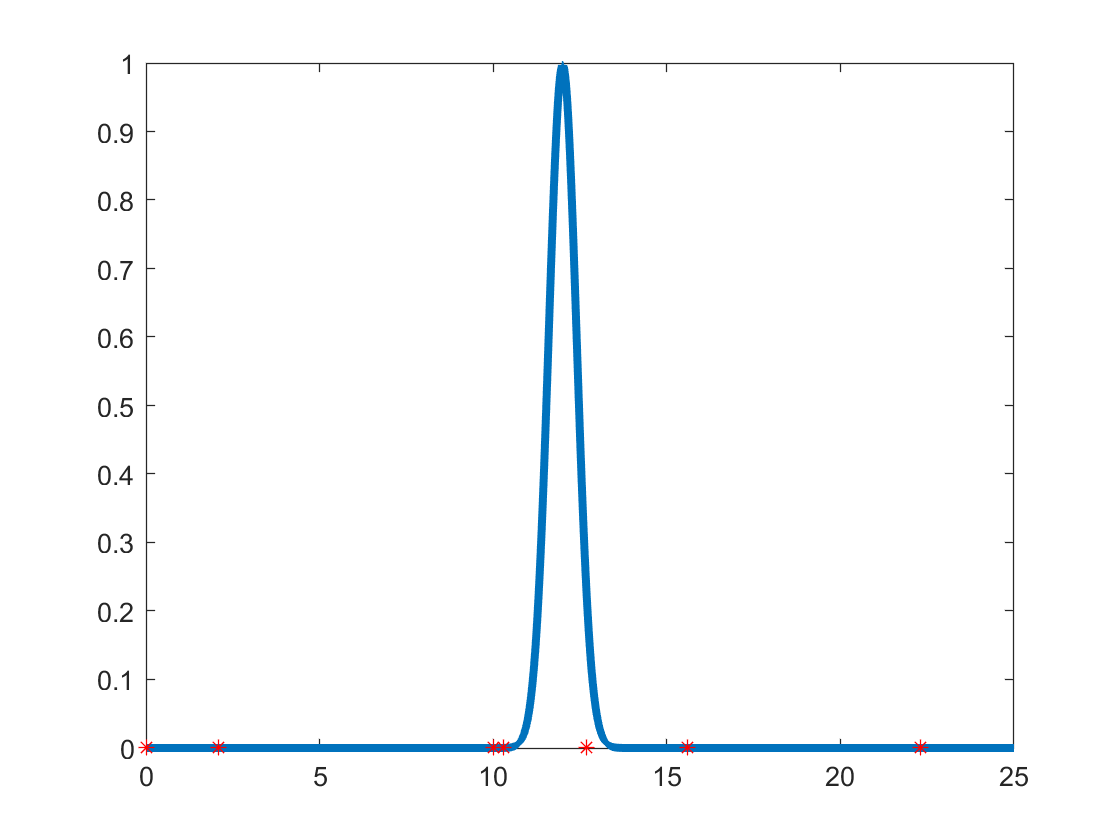

stairs(temp,distribution,"Linewidth",3)
hold on
plot(badData,0,'*r')
hold off

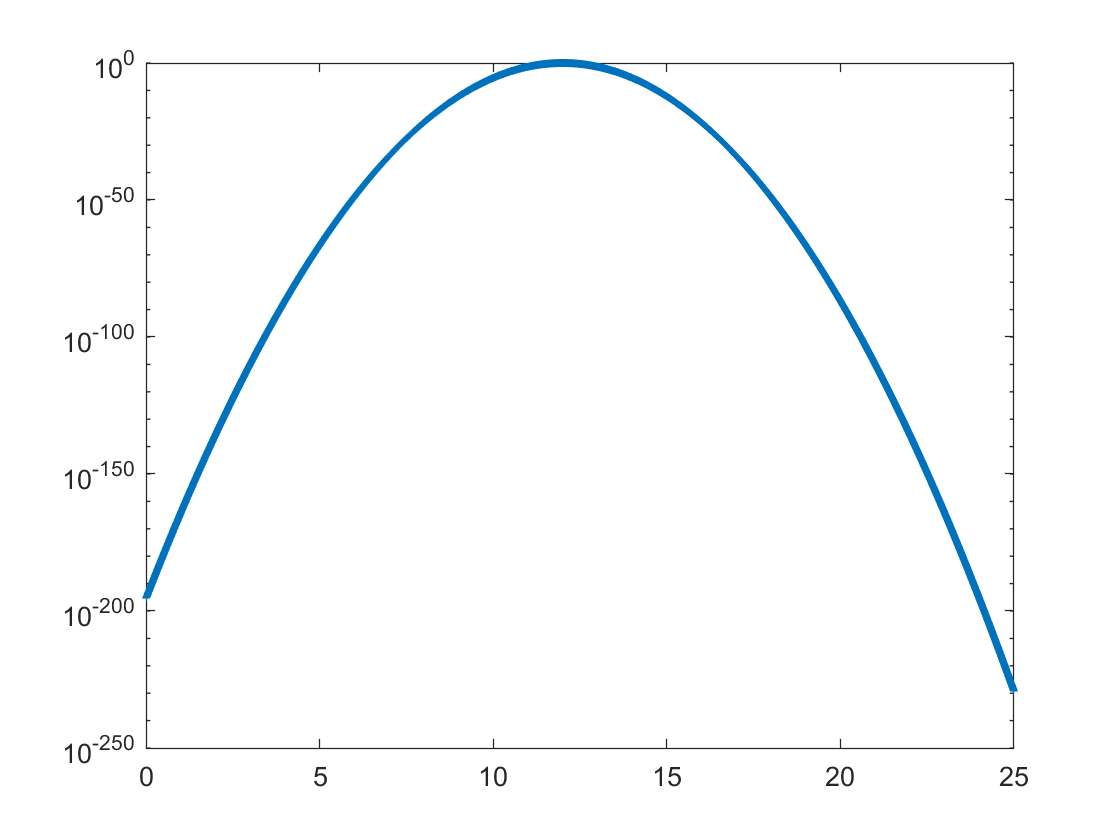

stairs(temp,distribution,"Linewidth",3)
set(gca, 'Yscale', 'log')

for each outlier we are going to find the sigma associated with it

for i = 1:length(badData)
    probability(i) = cdf(goodData, badData(i));
    sigma(i) = -norminv(probability(i));
end
badData

badData =    10.0000   10.3000    2.1000         0         0   15.6000   22.3000   12.7000


probability

probability =     0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    0.9599


sigma

sigma =     5.0000    4.2500   24.7500   30.0000   30.0000      -Inf      -Inf   -1.7500


        2. Statistical question: 

**"What is the probability that the good data is in the unacceptable data range?"**

I've considered this question because while some data might look less average than normal, there is still a chance that it is actual data and the deviation from the mean is caused by chance rather than it being an outlier that is statistically significant.

        3. Mathematically asked statistical question

**cdf(sigma = - cutoff sigma)+(1-cdf(sigma = + cutoff sigma)**

        4. Create a table

If I take out any data that's more than 3 sigma away from the mean, there is going to be four categories:

Group 1: Within 3 sigma data that was correctly identified as legitimate

Group 2: Within 3 sigma data that was incorrectly identified as legitimate (bad data that looks right)

group 3: Outside 3 sigma range that was thrown out incorrectly (good data off acceptable range)

Group 4: Outside 3 sigma range bad data points that were thrown out correctly

group1 = round(getCdfOfSigma(goodData,3)*100000) 

group1 = 99730

% I used round because the 3 sigma value didn't land on an exact point
group2 = howManyWithinRange(goodData,badData,3)

group2 = 1

group3 = 100000-group1

group3 = 270

group4 = length(badData)-group2

group4 = 7

B) How does it depend on the threshhold? 

I chose sigma values to check on from 1-5 and found how many good points were excluded while being actual data (group 3 values)

C) Are there mistakes (bad data getting in?)

Group 2 values show the bad data that has made it into the acceptable range

For sigma = 1:

group1 = round(getCdfOfSigma(goodData,1)*100000);
group2 = howManyWithinRange(goodData,badData,1)

group2 = 0

group3 = 100000-group1

group3 = 31731

group4 = length(badData)-group2;

For sigma = 2:

group1 = round(getCdfOfSigma(goodData,2)*100000) ;
group2 = howManyWithinRange(goodData,badData,2)

group2 = 1

group3 = 100000-group1

group3 = 4550

group4 = length(badData)-group2;

For sigma = 4:

group1 = round(getCdfOfSigma(goodData,4)*100000) ;
group2 = howManyWithinRange(goodData,badData,4)

group2 = 1

group3 = 100000-group1

group3 = 6

group4 = length(badData)-group2;

For sigma = 5:

group1 = round(getCdfOfSigma(goodData,5)*100000) ;
group2 = howManyWithinRange(goodData,badData,5)

group2 = 3

group3 = 100000-group1

group3 = 0

group4 = length(badData)-group2;

While we included more actual data points making the acceptable range a higher value of sigma, there were also more bad data points that looked acceptable.

*Problem 2*

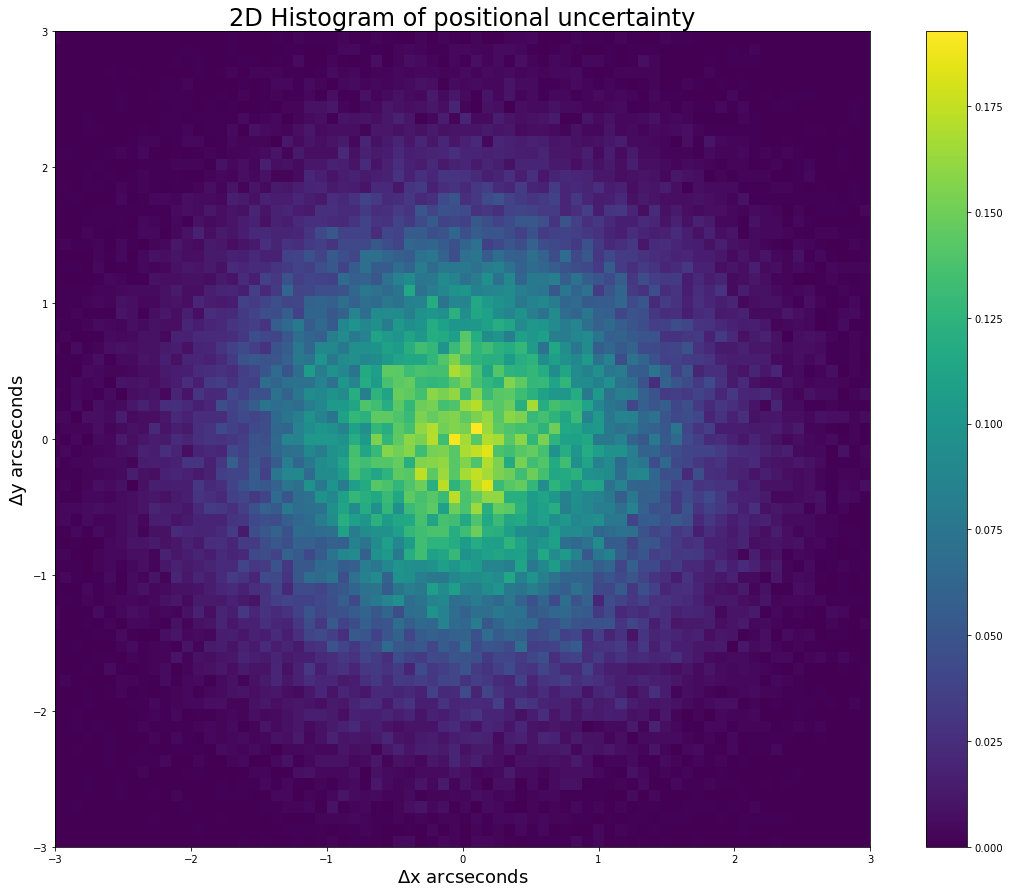

- Question in words:

**What is the probability that the actual signal is outside the acceptable sigma range?**

          2. Math:

probability = cdf(sigma = - 5)+(1-cdf(sigma = + 5)

*Problem 3*

- **What is the probability that our data point (6800) is produced by chance?**

- 1 ray/minute*60minutes/hour*8 hours = 420 rays/day* 15 days = 6300 rays average

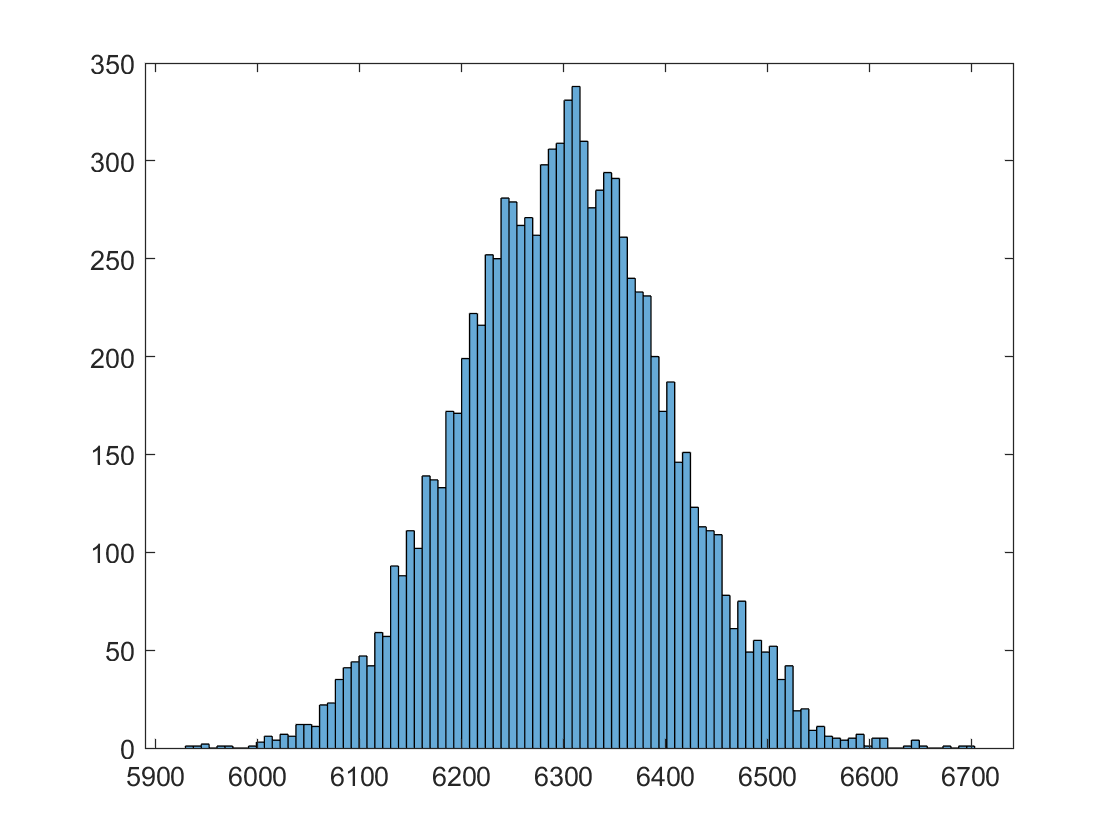

sigma = 100; % I came up with a random sigma
value15days = normrnd(6300,sigma,100);
vec = value15days(:);
histogram(vec,100)

area = zeros(100); 
areaVector = area(:); %idk why I came up with all this but now I can calculate cdf of a histogram where I only need the value of sigma and mean and given value to claulate how off it is
areaVector(1) = vec(1);
for i = 2:100
    areaVector(i) = vec(i-1)+vec(i);
end
sigmaValue = (6800-6300)/sigma

sigmaValue = 5

if abs(sigmaValue) >= 5
    fprintf("It's inacceptable")
end

It's inacceptable

**List of functions**

Function that returns cdf in the range of a certain number of sigmas give the pdf and number of sigmas

function a = getCdfOfSigma(pd,x)         
    mu1 = mean(pd);                     
    sigma1 = x*std(pd);                 
    a = cdf(pd,mu1+sigma1)-cdf(pd,mu1-sigma1);
end

Function that returns number of points

function b = howManyWithinRange(pd,x,sigma2)
    b = 0;
    for i = 1:length(x)
        probability(i) = cdf(pd, x(i));
        sigma(i) = -norminv(probability(i));
        if abs(sigma(i)) <= sigma2
            b=b+1;
        end
    end
end